%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_pIns.mat'];
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj,'glmestimate','pIns');
        allsubjid(plotidx)=subj{:};
        allsubjlayer{plotidx}=layerwisestat;
        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7484 subject has  no sampled cluster


allsubjid =         7361        7375        7376        7383        7402        7403        7404        7405        7408        7414        7415        7425        7426        7433        7434        7435        7443        7444        7445        7448        7449        7452        7453        7454        7455        7456        7457        7468        7469        7482        7484        7485


% figure('Position',[100, 100, 2400, 1200]);
topdown_beta=cell(2,1);
bottom_beta=cell(2,1);
topdown_t=cell(2,1);
bottomup_t=cell(2,1);
for roi=1:2
    for subj=1:length(allsubjlayer)
        topdown_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1); %main effect of cognition
        bottom_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2); %main effect of pain

        topdown_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        bottomup_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);
        
                

        
    end
end


%save the output as a matrix, so I can do the plotting/stat in R
nproc=2;
nsubj=length(allsubjid);
nside=2;
td=array2table([topdown_beta{1};topdown_beta{2}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottom_beta{1};bottom_beta{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

pIns=[td;bu];

pIns.subjid=string(repmat(allsubjid',nproc*nside,1));

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(pIns,[ pathtooutput 'pIns_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


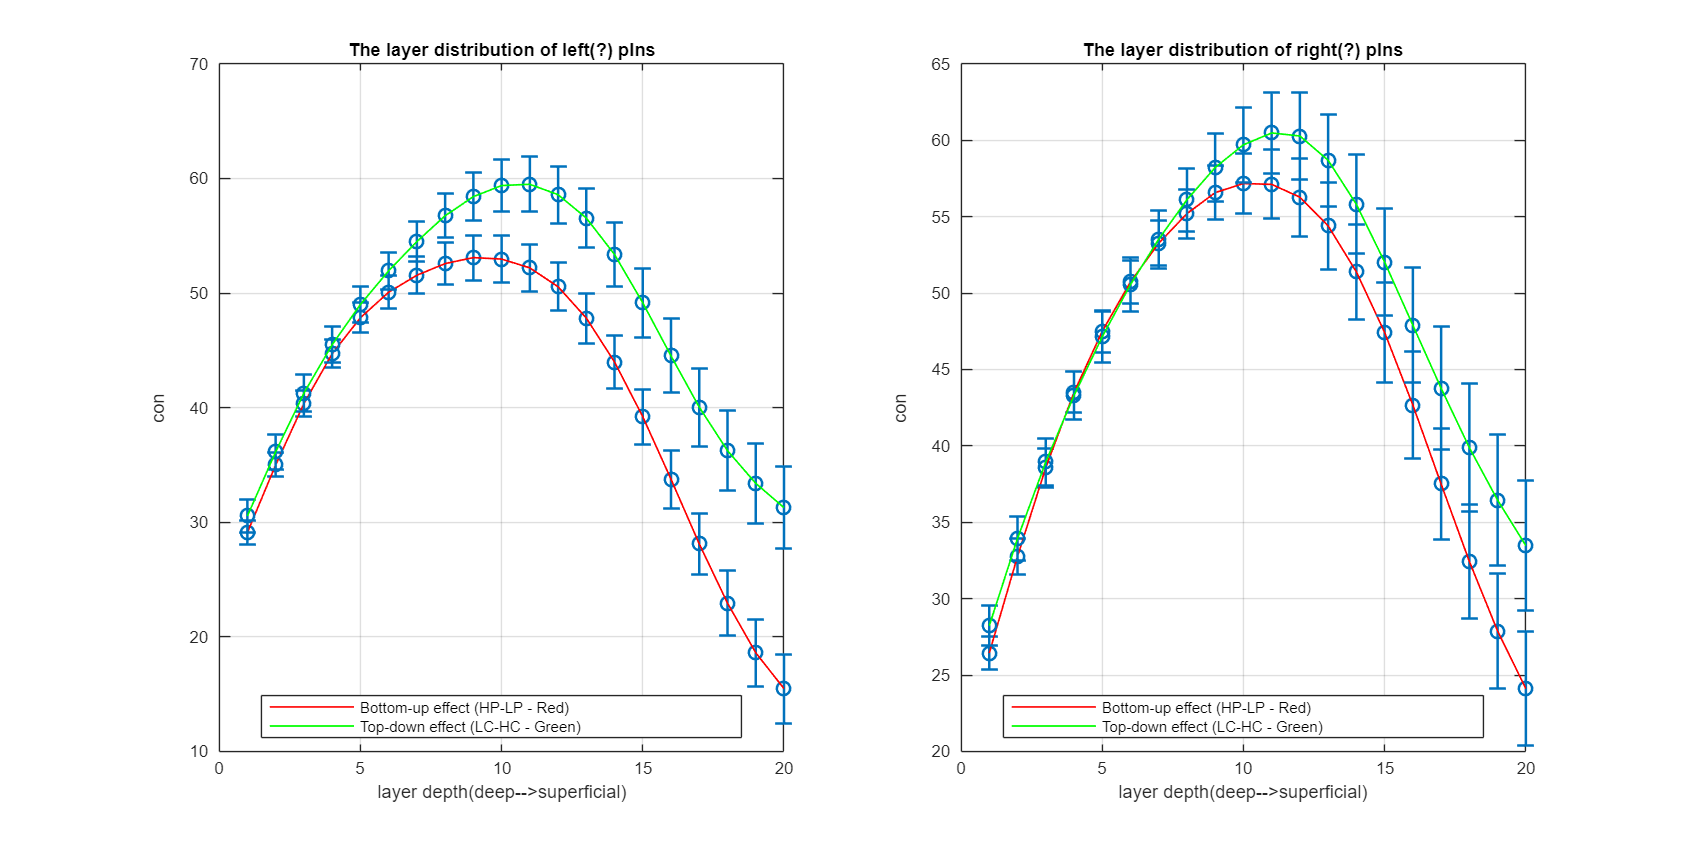

figure('Position',[100, 100, 2400, 1200]);

alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottom_beta{roitype,1}, topdown_beta{roitype,1}};
    for dataidx=1:2
        % Calculate column-wise mean and standard error
        if roitype==1
%             data=alldataroi1_beta{dataidx};
            titlenm='The layer distribution of left(?) pIns';
            
        elseif roitype==2
%             data=alldataroi2_bet{dataidx};
            titlenm='The layer distribution of right(?) pIns';
            
        end
        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end


% allsubjlayerresp=nan

for roi=1:1
    for subj=1:length(allsubjlayer)
        HCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        HCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);
        LCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,3);
        LCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,4);

        HCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        HCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);
        LCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,3);
        LCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,4);
        

        
        
    end
end


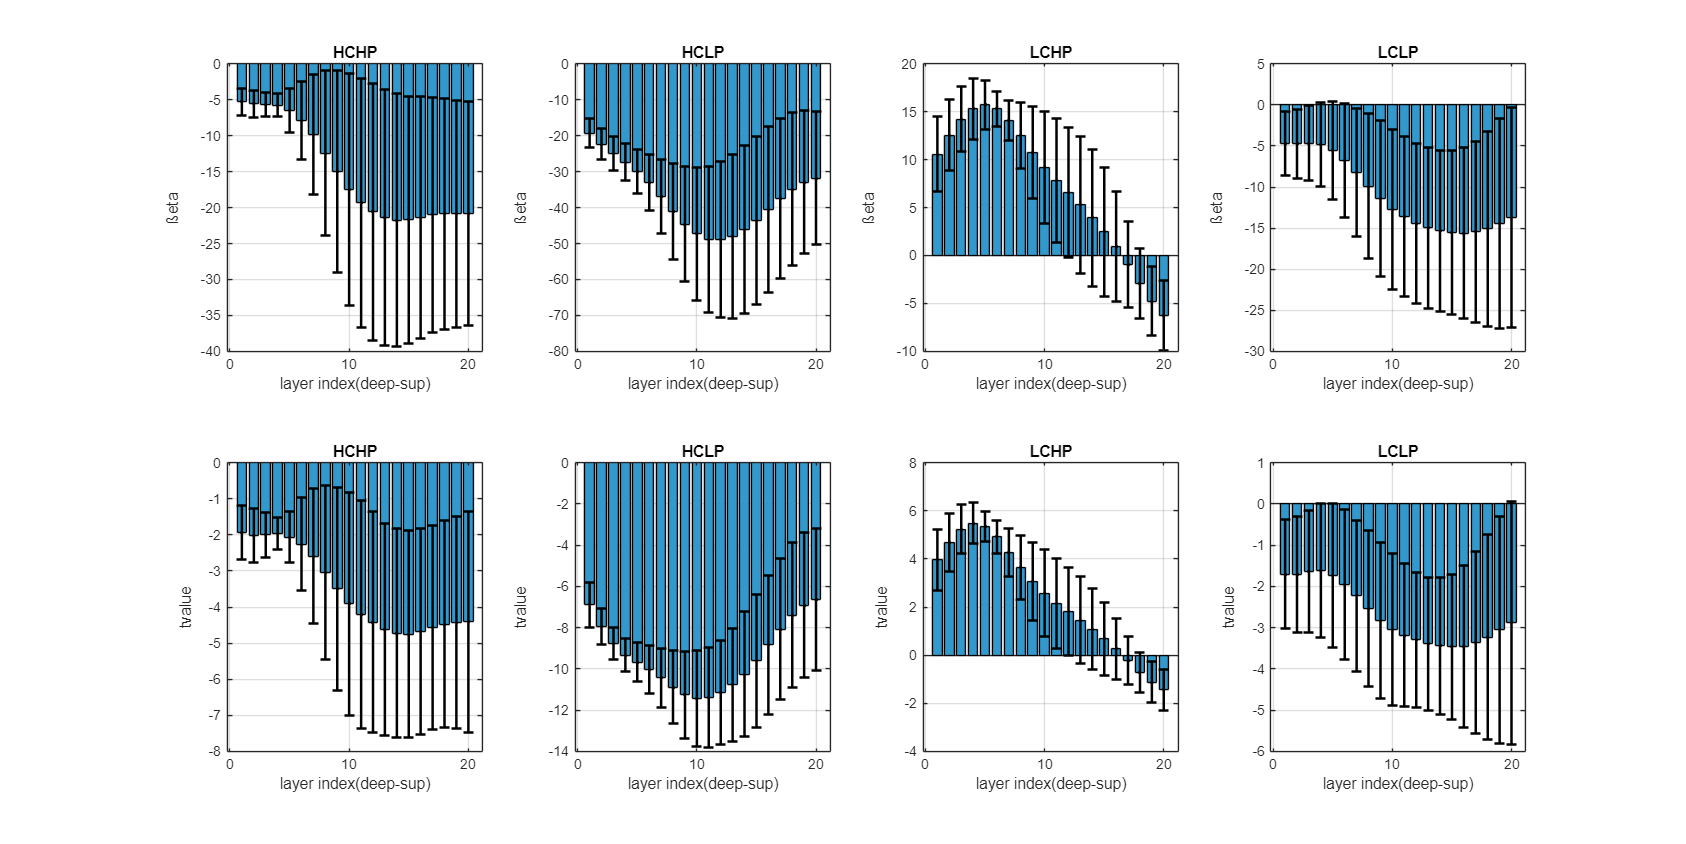

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldata2={HCHP_t, HCLP_t,LCHP_t,LCLP_t};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for maki=1:2
    for dataidx=1:4
        %     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
        %     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
        plotidx=plotidx+1;
        if maki==1
            data=alldata{dataidx};
            yaxisnm='ßeta';
        elseif maki==2
            data=alldata2{dataidx};
            yaxisnm='tvalue';
        end
        % Example matrix of size 10x20
        %     data = allsubjlayerresp; % Random data for demonstration
        
        % Calculate column-wise mean and standard deviation
        columnMeans = mean(data, 1); % Mean of each column
        columnStdDevs = std(data, 0, 1); % Standard deviation of each column
        
        % Create the bar plot
        subplot(2,4,plotidx)
        bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
        hold on;
        
        % Add error bars
        errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
            'k.', 'LineWidth', 1.5); % Error bars in black
        
        % Customize the plot
        xlabel('layer index(deep-sup)');
        ylabel(yaxisnm);
        title(alldatanm{dataidx});
        grid on;
        hold off;
    end
end



% Example matrix of size 10x20
data = allsubjlayerresp_T; % Random data for demonstration

% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
columnStdDevs = std(data, 0, 1); % Standard deviation of each column

% Create the bar plot
figure;
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('Column Index');
ylabel('Value');
title('Bar Plot with Error Bars (Mean ± Std Dev)');
grid on;
hold off;

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);

    HCHP(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    HCLP(subj,:)=allsubjlayer{subj}.beta(:,1,2);

    LCHP(subj,:)=allsubjlayer{subj}.beta(:,1,3);
    LCLP(subj,:)=allsubjlayer{subj}.beta(:,1,4);

%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end


figure;
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for dataidx=1:4
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
    plotidx=plotidx+1;
    data=alldata{dataidx};
% Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
    
    % Calculate column-wise mean and standard deviation
    columnMeans = mean(data, 1); % Mean of each column
    columnStdDevs = std(data, 0, 1); % Standard deviation of each column
    
    % Create the bar plot
    subplot(2,2,plotidx)
    bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
    hold on;
    
    % Add error bars
    errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
        'k.', 'LineWidth', 1.5); % Error bars in black
    
    % Customize the plot
    xlabel('layer index(deep-sup)');
    ylabel('ßeta');
    title(alldatanm{dataidx});
    grid on;
    hold off;
end


histogram(HC_onpain)

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
    HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
    LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);


%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

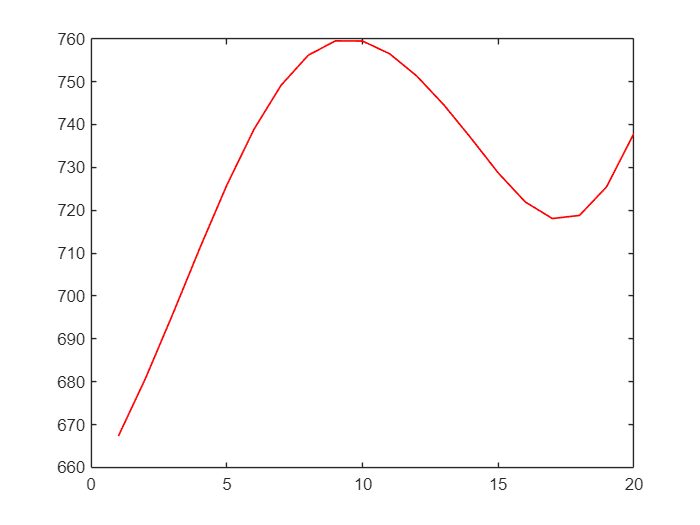

%check the bold response layerdependency
load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_pIns.mat')
figure;
vertexmean=squeeze(mean(interimdata_columns{1,2}{1,1},1));
layermean=mean(vertexmean,2)';
plot(1:20, layermean, '-r', 'LineWidth', 1);